# `Project 2: `**How do different policies, movements, and interactions as factors of social connectivity in migrant workers' dorms affect the transmission of disease?**

# `Sparsh Gupta, Belén Hutchins, Swasti Jain`

#### `Computational Essay`

`sgupta1@olin.edu                   sjain1@olin.edu                  bhutchins@olin.edu`

## `Question `

**How do different policies, movements, and interactions as factors of social connectivity in migrant workers' dorms affect the transmission of disease?**

Covid-19 has affected a wide variety of communities in the past 3 years. For this project, we decided to focus on how it affected migrant workers living in the Singapore worker dorms as a case study. Specifically, how do different living conditions and restricted interactions between migrant workers affect the transmission of disease?

The question is explanatory because it assesses how the differences within the models’ structure, pods, and factors lead to differing results. 

In this project, we aim to understand how interactions between the workers in different pods would affect the transmission of the disease. Within each pod, we looked at modeling factors like overcrowdedness, quality of living conditions, difficulties in social distancing, and inflexible work commitments as main features contributing to the worker dorms’ high influx of infection. Doing research on how migrant workers were treated during the start of the pandemic was also beneficial as we were able to learn how factors that are socially acceptable but problematic, can lead to serious issues that primarily affect marginalised groups.

It is interesting because we want to model how government policy changes (for example, declaring ‘isolation areas’), the movements of workers between dorms and construction sites, and interactions between the workers in different pods would affect the transmission of disease in a population of migrant workers. Factors like overcrowded & poor living conditions, difficulties in social distancing, and inflexible work commitments are also responsible for different social connectivity levels between workers and pods, as was seen in real-life, though they majorly just contribute to the above policies, movements, and interactions factors.

To gather background information about the question, a literature search is conducted in the form of a Research Synthesis Matrix:

Research Synthesis Matrix

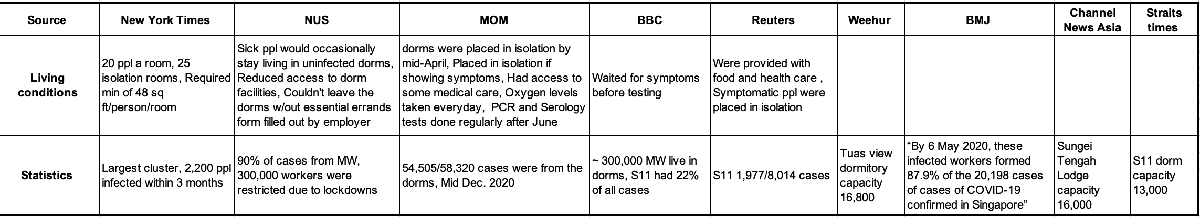

Research Matrix Sources: 

- New York Times: [https://www.nytimes.com/interactive/2020/04/28/world/asia/coronavirus-singapore-migrants.html](https://www.nytimes.com/interactive/2020/04/28/world/asia/coronavirus-singapore-migrants.html)

- NUS: [https://law.nus.edu.sg/impact/covid-19-shedding-light-on-the-plight-and-laws-regulating-migrant-worker-dormitories-in-singapore/](https://law.nus.edu.sg/impact/covid-19-shedding-light-on-the-plight-and-laws-regulating-migrant-worker-dormitories-in-singapore/)

- MOM: [https://www.mom.gov.sg/newsroom/press-releases/2020/1214-measures-to-contain-the-covid-19-outbreak-in-migrant-worker-dormitories](https://www.mom.gov.sg/newsroom/press-releases/2020/1214-measures-to-contain-the-covid-19-outbreak-in-migrant-worker-dormitories)

- BBC: [https://www.bbc.com/news/world-asia-55314862](https://www.bbc.com/news/world-asia-55314862)

- Reuters: [https://www.reuters.com/article/us-health-coronavirus-singapore-migrants/the-s11-dormitory-inside-singapores-biggest-coronavirus-cluster-idUSKBN2230RK](https://www.reuters.com/article/us-health-coronavirus-singapore-migrants/the-s11-dormitory-inside-singapores-biggest-coronavirus-cluster-idUSKBN2230RK)

- Weehur: [https://www.weehur.com.sg/business_projects/tuas-view-dormitory/#:~:text=At%20a%20capacity%20of%2016%2C800,largest%20worker's%20dormitory%20in%20Singapore](https://www.weehur.com.sg/business_projects/tuas-view-dormitory/#:~:text=At%20a%20capacity%20of%2016%2C800,largest%20worker's%20dormitory%20in%20Singapore)

- BMJ: [https://oem.bmj.com/content/77/9/634](https://oem.bmj.com/content/77/9/634)

- Channel News Asia: [https://www.channelnewsasia.com/singapore/stay-home-notice-covid-19-sungei-tengah-lodge-worker-dorms-630601](https://www.channelnewsasia.com/singapore/stay-home-notice-covid-19-sungei-tengah-lodge-worker-dorms-630601)

- Straits times: [https://www.straitstimes.com/politics/parliament-conditions-at-punggol-dormitory-could-have-been-better-maintained-as-it-was-made](https://www.straitstimes.com/politics/parliament-conditions-at-punggol-dormitory-could-have-been-better-maintained-as-it-was-made)

We research a variety of the conditions surrounding the sharp increase in Covid-19 cases in Singapore. These conditions include the increase in testing in the worker dormitories, the difference in living conditions in the dormitories when compared to the general Singapore population, along with statistics about the spread of Covid in the migrant worker dormitories. The background information helped us better understand why cases spiked the way they did and if our model was accurate based on our knowledge of the situation. Our research also gave us empathy for the migrant workers as we read their stories, gained insight on their situation, and saw them as more than just data points. Our most relevant findings were that there are around 300,000 migrant workers living in the dormitories which have up to 20 people a room with a required minimum of 48 square feet per person per room (New York Times). These dormitories are clearly an overcrowded environment which is perfect breeding ground for Covid. In addition, the government's method of testing was more reactive than preventative. Not only were PCR tests mostly administered to those that were already showing symptoms, symptomatic individuals would occasionally continue to stay in their otherwise uninfected rooms. These factors help to explain why there was such a sudden increase in cases among migrant workers at the start of the pandemic as depicted in the graph below. 

## `Methodology/Model`

The social connectivity digram for the podded-agent-based SIR model

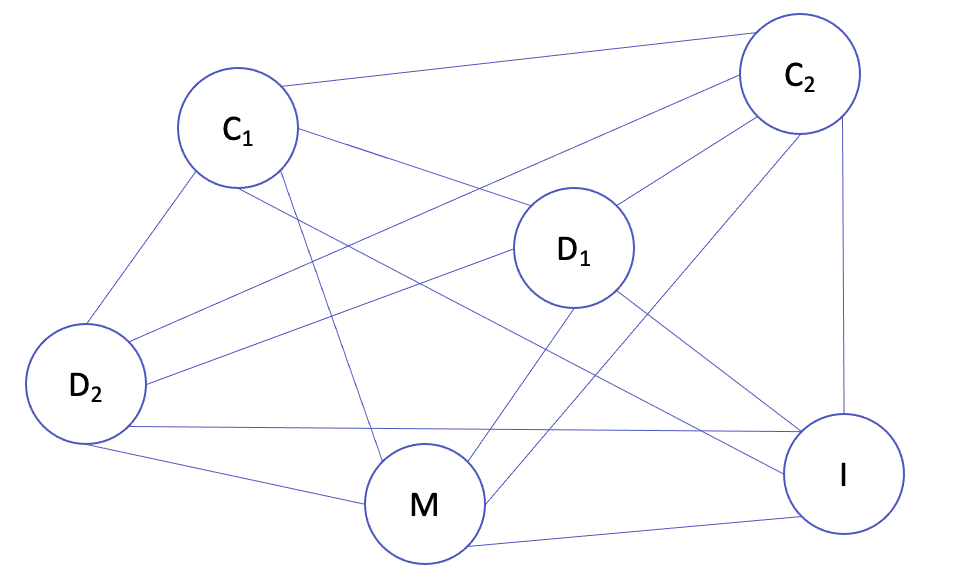

The circles/nodes in the diagram represent pods with distinct number of individuals inside them and the connections/edges represent a complete graph because all nodes are inter-connected.

The update equations being used in the agent-based SIR model


$$I = I \ | \  v_{infect} \ \& \ (\text{~} R)
\\
R = R \ | \ (I \ \& \ v_{recover})
\\
I = I \ \& \ (\text{~}R)
\\
\\
\text{dim = length}(I_{v_{0}})
\\
I_{h} = \text{zeros(dim, T)}
\\
R_{h} = \text{zeros(dim, T)}
\\
S_{h} = \text{ones(dim, T)} - I_{h} - R_{h}$$


The agent-based SIR model for modeling the social connectivity and transmission of disease in migrants workers' has multiple assumptions, but the greatest one is that the individuals inside different pods have unequal edge weights so that the infections spread in different intensities within the pods, but the edge weights among individuals across different pods have same edge weights which assumes that individuals can infect each other across pods with the same probabilities. This assumption can have some minor bias on the modeling results. Also, to reduce model complexity, it is assumed that the infections caused from the population outside the model (i.e. Singapore's general population) and the infections caused to the external-model population from inside the model cancel out each other, so that the flow of infections do not affect the model.

The equation inputs used in the agent-based SIR model are:

- $I$ represents infecting non-recovered individuals

- $R$ represents recovering infected individuals

- $v_{infect}$ represents the random values obtained from the infection rate

- $v_{recover}$ represents the random values obtained from the recovery rate

- $I_{v_0}$ represents the initial infection state

- $dim$ represents the dimensions of the initial infection state

- $T$ represents the number of timesteps of simulation

- $I_h, R_h, S_h$ represent the infected, recovered, and susceptible state history respectively

The pods used in the model are:

- $D_1$ represents the overcrowded dorm in the model. It has higher infectivity due to higher population density, and close contact with other individuals in the pod.

- $D_2$ represents a normal dorm in the model. It is similar to the living conditions of the general population in Singapore with normal rates on infection.

- $C_1$ represents the outbreak-center construction site in the model. This pod is a place where migrant workers would often interact at and spread the infection in higher rates.

- $C_2$ represents another construction site in the model. It also represents a place where migrant workers interacted but with lower infectivity rate than compared to $C_1$.

- $M$ represents the mall in the model. The pod represents a location where individuals would interact with other people and have higher infection rates.

- $I$ represents the isolated area/site in the model. It has the lowest infectivity due to barrier in close contact with other individuals in the pod and maximum isolation precautions.

The parameters in the model (edge weights) among the individual pods were set by taking into account the following:

- $n_{D_1}$: It is set considering the high rate of infection transmission in the overcrowded dorm of migrant workers $D_1$.

- $n_{D_2}$: It is set according to the normal rates of COVID-19 transmission observed in general population.

- $n_{C_1}$: It is determined by considering that this is one of the outbreak-center pods in the model with high chances of disease transmission.

- $n_{C_2}$: It is determined according to the normal rates of COVID-19 transmission observed in the real-life scenario pod.

- $n_M$: It is set according to the high infection rates observed due to it being one of the outbreak-center pods in the model.

- $n_I$: It is set considering the low rate of infection transmission as it being an isolated pod $I$.

Verification:

The following verification facts used to ensure that the model functions as expected:

- Adjacency Matrix M for pods: The elements in the diagonal of an adjacency matrix should be equal to 0.

% assert(all(diag(M_pods) == 0), 'The diagonal of M should be zeros')

## **Result**

In this model, the sizes of the pods have been set according to the data observed in the the case-study of the situation of the migrant workers in Singapore during COVID-19. The edge weights which affect the rates of disease transmission have also been determined according to the rates of transmission observed within the pods in the case-study.

Therefore, the values of two parameters that affect the model is determined by using parameter sweeps:

- infection_rate: This value is a random probabilistic value which determines the rate of transmission of infection.

- recovery_rate: This value is a random probabilistic value which determines the rate of recovery from the disease.

We need to determine the optimal values of infection_rate and recovery_rate to make the model have the desired total number of peak infections as observed in the case-study data.

#### Sensitivity Analysis using Parameter Sweeps

The code below sets the simulation variables and sets up parameter sweeps across infection rates and recovery rates for the model.

% Parameter Sweep for infection rate

% Setting up model values
D_1 = 1000;
n_d1 = 10;
D_2 = 390;
n_d2 = 5;
C_1 = 150;
n_c1 = 7;
C_2 = 200;
n_c2 = 6;
M = 160;
n_m = 6;
I = 100;
n_i = 1;

The function below creates the desired pods which is used to simulate the model using intialized values of model variables.

% Making an adjacency matrix with the desired pods
M_pods = makePods(D_1, n_d1, D_2, n_d2, C_1, n_c1, C_2, n_c2, M, n_m, I, n_i);

% Variables for parameter sweep
infection_all = linspace(0.0001, 0.002, 100);
recovery_all = 0.06;

The code below iterates over the infectivity sweep of the model for the desired range of parameter values and records the data for the maximum number of infections in each simulation.

Max_all = zeros(size(infection_all));

for i = 1 : length(infection_all)
     
    infection_temp = infection_all(i); 

    Iv0 = zeros(D_1 + D_2 + C_1 + C_2 + M + I, 1);
    Iv0(1) = 1;
    rng(101)
    [~, Ih, ~] = simulate_absir(M_pods, Iv0, 100, infection_temp, recovery_all);
    I_count = sum(Ih, 1);
   
    Max_all(i) = max(I_count);
end

The following code plots the simulation results of the parameter sweep over the parameter infection_rate.

% Visualize the results
figure()
plot(infection_all, Max_all)
xlabel('Infection Rate (probability of transmission)')
ylabel('Max Infected')
title('Parameter Sweep: infection rate')

As we can observe from the above graph, there is a steep increase when the infection_rate increases initially but then it starts to flatten as we reach a certain threshold value.

% Parameter Sweep for recovery rate

infection_all = 0.005;
recovery_all = linspace(0.01, 0.2, 100);

The code below iterates over the recovery_rate sweep of the model for the desired range of parameter values and records the data for the maximum number of infections in each simulation.

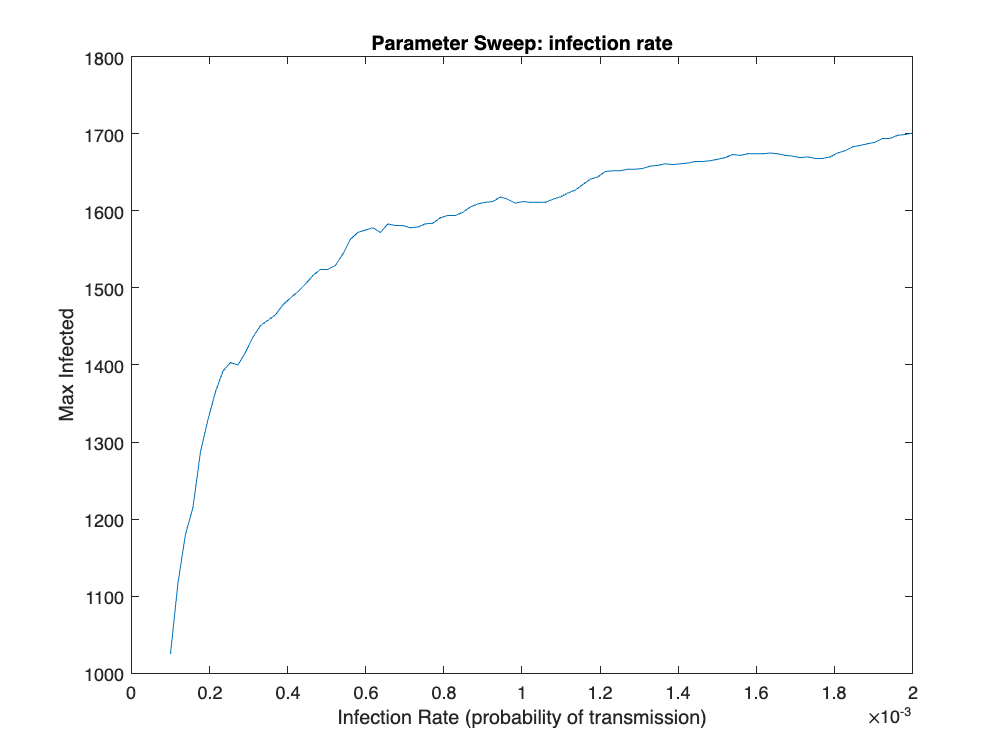

Max_all = zeros(size(recovery_all));

for j = 1 : length(recovery_all)

   
    recovery_temp = recovery_all(j); 

    Iv0 = zeros(D_1 + D_2 + C_1 + C_2 + M + I, 1);
    Iv0(1) = 1;
    rng(101)
    [~, Ih, ~] = simulate_absir(M_pods, Iv0, 100, infection_all, recovery_temp);
    I_count = sum(Ih, 1);
   
    Max_all(j) = max(I_count);
end

The following code plots the simulation results of the parameter sweep over the parameter recovery_rate.

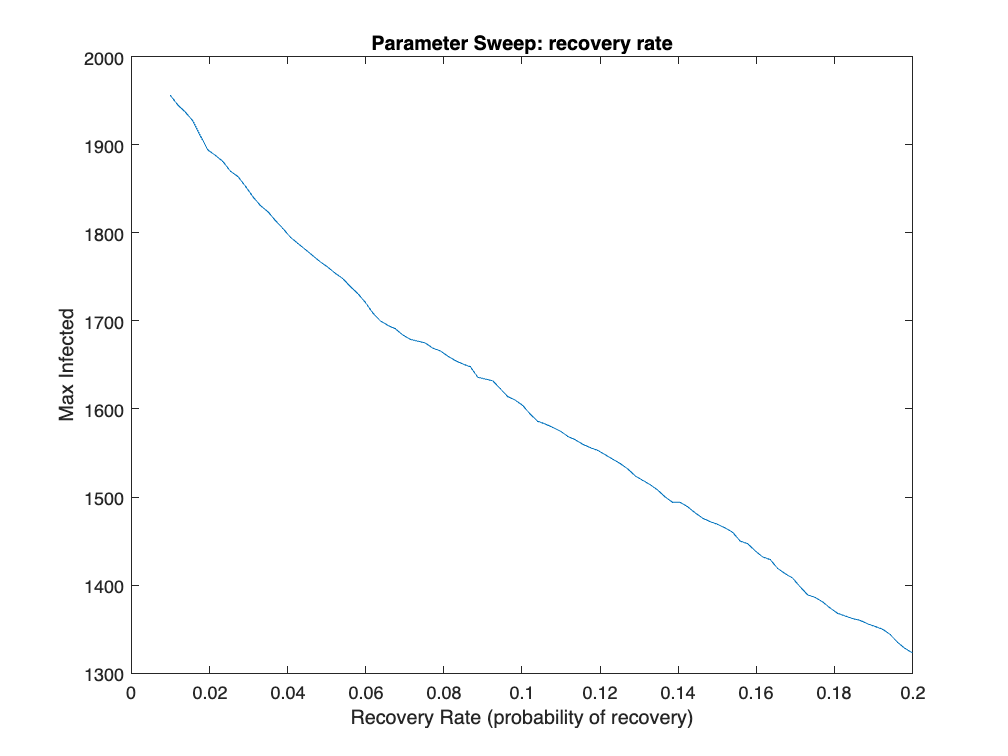

% Visualize the results
figure()
plot(recovery_all, Max_all)
xlabel('Recovery Rate (probability of recovery)')
ylabel('Max Infected')
title('Parameter Sweep: recovery rate')

As we can infer from the graph above, the maximum number of infections in the model simulation constantly decreases as the recovery_rate linearly increases.

Now, we can plug in the optimal values of infection_rate and recovery_rate desired obtained from the above parameter sweeps, to analyze the effect of modifying individual pod edge weights on the total number of infections in each pod by conducting another parameter sweep.

The initial values are set for the model edge weights and pod sizes using the following code.

% Setting up model values
D_1 = 1000;
n_d1 = 10;
D_2 = 390;
n_d2 = 5;
C_1 = 150; 
n_c1 = 7;
C_2 = 200;
n_c2 = 6;
M = 160;
n_m = 6;
I = 100;
n_i = 1;

Linearly spaced values for each edge weight is also created which will be used to loop over in the parameter seeep function.

n_d1_all = linspace(1, 10, 10);
n_d2_all = linspace(1, 10, 10);
n_c1_all = linspace(1, 10, 10);
n_c2_all = linspace(1, 10, 10);
n_m_all = linspace(1, 10, 10);
n_i_all = linspace(1, 10, 10);

 Values for infection rate, recovery rate and the number of simulation timsteps is also intialized.

infection_rate = 0.001;
recovery_rate = 0.06;

T_simulation = 100;

The code below iterates over the edge weights of each pod of the model for the desired range of edge weight-values (which is 1 to 10) and records the data for the maximum number of infections in each pod in every simulation. In each loop, the individual pods are made using the 'makePods' function to simulate the model for every pod using different values of its edge weight.

% Reserve space for the resulting metric values
Max_all_d1 = zeros(size(n_d1_all));
Max_all_d2 = zeros(size(n_d2_all));
Max_all_c1 = zeros(size(n_c1_all));
Max_all_c2 = zeros(size(n_c2_all));
Max_all_m = zeros(size(n_m_all));
Max_all_i = zeros(size(n_i_all));


for j = 1 : 10
   
    n_d1_temp = n_d1_all(j);
    n_d2_temp = n_d2_all(j);
    n_c1_temp = n_c1_all(j);
    n_c2_temp = n_c2_all(j);
    n_m_temp = n_m_all(j);
    n_i_temp = n_i_all(j);

    
    M_pods_d1 = makePods(D_1, n_d1_temp, D_2, n_d2, C_1, n_c1, C_2, n_c2, M, n_m, I, n_i);
    Iv0_D1 = zeros(D_1, 1);
    Iv0_D1(1) = 1;
    rng(101)
    [~, Ih_D1, ~] = simulate_absir(M_pods_d1(1:D_1, 1:D_1), ...
        Iv0_D1, T_simulation, infection_rate, recovery_rate);
    I_count_D1 = sum(Ih_D1, 1);

    M_pods_d2 = makePods(D_1, n_d1, D_2, n_d2_temp, C_1, n_c1, C_2, n_c2, M, n_m, I, n_i);
    Iv0_D2 = zeros(D_2, 1);
    Iv0_D2(1) = 1;
    rng(101)
    [~, Ih_D2, ~] = simulate_absir(M_pods_d2(1+D_1 : D_2+D_1, 1+D_1 : D_2+D_1), ...
        Iv0_D2, T_simulation, infection_rate, recovery_rate);
    I_count_D2 = sum(Ih_D2, 1);

    M_pods_c1 = makePods(D_1, n_d1, D_2, n_d2, C_1, n_c1_temp, C_2, n_c2, M, n_m, I, n_i);
    Iv0_C1 = zeros(C_1, 1);
    Iv0_C1(1) = 1;
    rng(101)
    [~, Ih_C1, ~] = simulate_absir(M_pods_c1(1+D_1+D_2 : D_1+D_2+C_1, ...
        1+D_1+D_2 : D_1+D_2+C_1), Iv0_C1, T_simulation, infection_rate, recovery_rate);
    I_count_C1 = sum(Ih_C1, 1);

    M_pods_c2 = makePods(D_1, n_d1, D_2, n_d2, C_1, n_c1, C_2, n_c2_temp, M, n_m, I, n_i);
    Iv0_C2 = zeros(C_2, 1);
    Iv0_C2(1) = 1;
    rng(101)
    [~, Ih_C2, ~] = simulate_absir(M_pods_c2(1+D_1+D_2+C_1: D_1+D_2+C_1+C_2, ...
        1+D_1+D_2+C_1: D_1+D_2+C_1+C_2), Iv0_C2, T_simulation, infection_rate, recovery_rate);
    I_count_C2 = sum(Ih_C2, 1);

    M_pods_m = makePods(D_1, n_d1, D_2, n_d2, C_1, n_c1, C_2, n_c2, M, n_m_temp, I, n_i);
    Iv0_M = zeros(M, 1);
    Iv0_M(1) = 1;
    rng(101)
    [~, Ih_M, ~] = simulate_absir(M_pods_m(1+D_1+D_2+C_1+C_2: D_1+D_2+C_1+C_2+M, ...
        1+D_1+D_2+C_1+C_2: D_1+D_2+C_1+C_2+M), Iv0_M, T_simulation, infection_rate, recovery_rate);
    I_count_M = sum(Ih_M, 1);

    M_pods_i = makePods(D_1, n_d1, D_2, n_d2, C_1, n_c1, C_2, n_c2, M, n_m, I, n_i_temp);
    Iv0_I = zeros(I, 1);
    Iv0_I(1) = 1;
    rng(101)
    [~, Ih_I, ~] = simulate_absir(M_pods_i(1+D_1+D_2+C_1+C_2+M: D_1+D_2+C_1+C_2+M+I, ...
        1+D_1+D_2+C_1+C_2+M: D_1+D_2+C_1+C_2+M+I), Iv0_I, T_simulation, infection_rate, recovery_rate);
    I_count_I = sum(Ih_I, 1);


    % Compute and store the metric value    
    Max_all_d1(j) = max(I_count_D1);
    Max_all_d2(j) = max(I_count_D2);
    Max_all_c1(j) = max(I_count_C1);
    Max_all_c2(j) = max(I_count_C2);
    Max_all_m(j) = max(I_count_M);
    Max_all_i(j) = max(I_count_I);

end

The following code plots the simulation results of the parameter sweeps over the different values of edge weights for every individual pods using subplots.

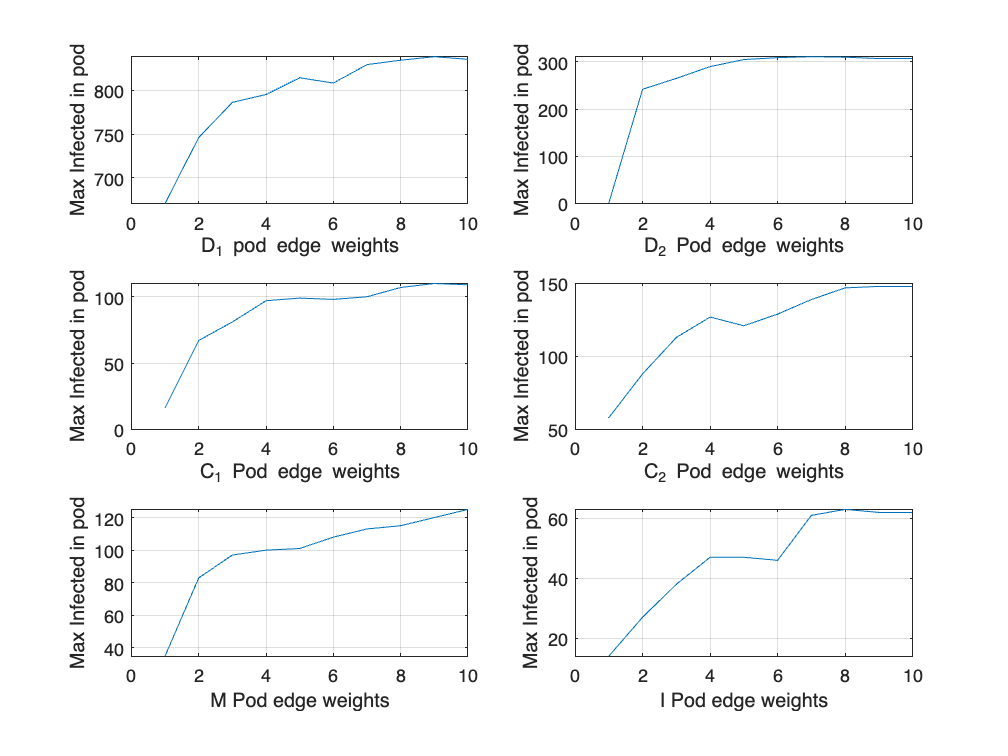

% Visualize the results
figure()
subplot(3,2,1)
plot(n_d1_all, Max_all_d1);
xlabel('D_1 pod edge weights')
ylabel('Max Infected in pod')
grid on;
subplot(3,2,2)
plot(n_d2_all, Max_all_d2);
xlabel('D_2 Pod edge weights')
ylabel('Max Infected in pod')
grid on;
subplot(3,2,3)
plot(n_c1_all, Max_all_c1);
xlabel('C_1 Pod edge weights')
ylabel('Max Infected in pod')
grid on;
subplot(3,2,4)
plot(n_c2_all, Max_all_c2);
xlabel('C_2 Pod edge weights')
ylabel('Max Infected in pod')
grid on;
subplot(3,2,5)
plot(n_m_all, Max_all_m);
xlabel('M Pod edge weights')
ylabel('Max Infected in pod')
grid on;
subplot(3,2,6)
plot(n_i_all, Max_all_i);
xlabel('I Pod edge weights')
ylabel('Max Infected in pod')
grid on;

The most important trends that are noticeable in the parameter sweeps are:

- The infection_rate and recovery_rate give predictable results in terms of the increasing and decreasing of the maximum number of infected people in different simulations. 

- However, they differ in the sense that the infection_rate vs max infected curve has a sharp rise in the beginning, which essentially means that a small increase of the parameter value initially has a greater effect compared to the increments in the value after reaching a certain threshold value, after which we observe a stable increase in max infected people. In the recovery_rate vs max infected curve, we see a gradual and stable decrease when increasing the value of the recovery_rate because they are inversely proportional to each other.

- We can infer from the final parameter sweeps conducted that manipulating different edge weights in individual pods affects the number of total infections. We also see that after a certain threshold value in some pods, when the cases were increasing when the edge weights were increased, the maximum inections started decreasing after this peak threshold value. For example, in pods $D_1$, $D_2$, and $I$.

The results of the parameter sweeps demonstrate how the model shows different trends of maximum number of infected people including steep or gradual curves of infection increase, peak total cases, etc. by varying different rates of infection and recovery rates, and the values of edge weights in individual pods.

#### Model Simulation 

The model focuses on two important aspects which are:

- **Pods:** A total number of six pods are created in the model to simulate infection transmission using the agent-based SIR model. The pods have very distinct features based on their characteristics and the previous data observed in our primary migrant workers' case-study. The most important characteristic is the unequal sizes of these pods which basically means that there are different numbers of individuals in each pod.

- **Edge-weights: **The edge-weights determine the rates of transmission of infection from an indivdual to other individuals. It is used within the pods to connect individuals for infection transmission rates with different intensities according to the case-study data as explained in the previous section. The edge-weights between individuals from two different pods are kept the same, whereas, the edge-weights within pods are unequal when compared to other pods.

The following code sets up the values of the number of people in every pod and the edge-weights used in the model:

% Model variables values

D_1 = 1000;
n_d1 = 10;
D_2 = 390;
n_d2 = 5;
C_1 = 150; 
n_c1 = 7;
C_2 = 200;
n_c2 = 6;
M = 160;
n_m = 6;
I = 100;
n_i = 1;

The following function takes the input of the variables used in the model to create a combined adjacency-matrix with different pods with different edge-weight values.

M_pods = makePods(D_1, n_d1, D_2, n_d2, C_1, n_c1, C_2, n_c2, M, n_m, I, n_i);

The pods created are plotted as a graph using the following code:

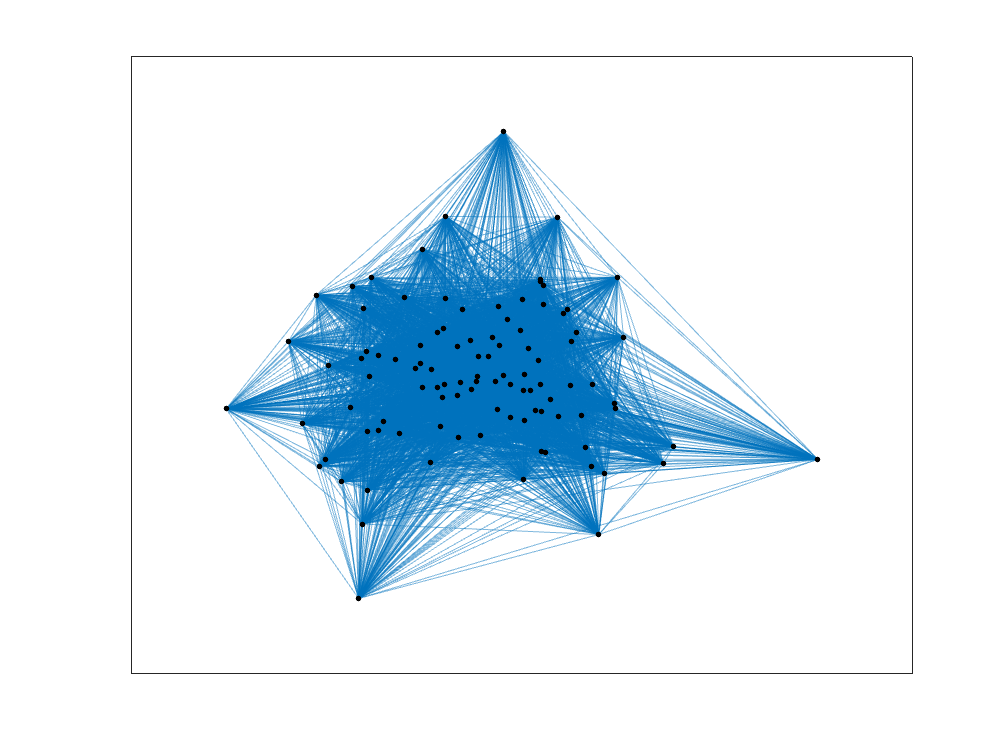

Graph_pod = graph(M_pods);
figure();
h = plot(Graph_pod, 'NodeColor', 'k', 'LineWidth', 0.1);

The above graph demonstrates the different clusters of pods in the model. Each pod consists of a different number of individuals which are connected through edges represented as points and lines respectively.

The following code is used to simulate the model for 100 timesteps using the obtained optimal values of infection_rate and recovery_rate from the parameter sweeps:

% Set parameter values
infection_rate = 0.001; recovery_rate = 0.06; 

T_simulation = 100; % timesteps

The code below initializes a zeros matrix with the size of the total number of individuals in the model. Then, the model is simulated as an agent-based SIR model to record the infection history of every individual. The total number of infected individuals in the simulation are then summed up at every timestep. It is used to return a count of total infected persons at every timestep in the model. 

% Simulate agent-based model
Iv0 = zeros(D_1 + D_2 + C_1 + C_2 + M + I, 1);
Iv0(1) = 1;
rng(101)
[~, Ih, ~] = simulate_absir(M_pods, Iv0, T_simulation, infection_rate, recovery_rate);
I_count = sum(Ih, 1);

Then, the simulation is plotted as a graph to infer the total number of infected people in the population throughout the simulation.

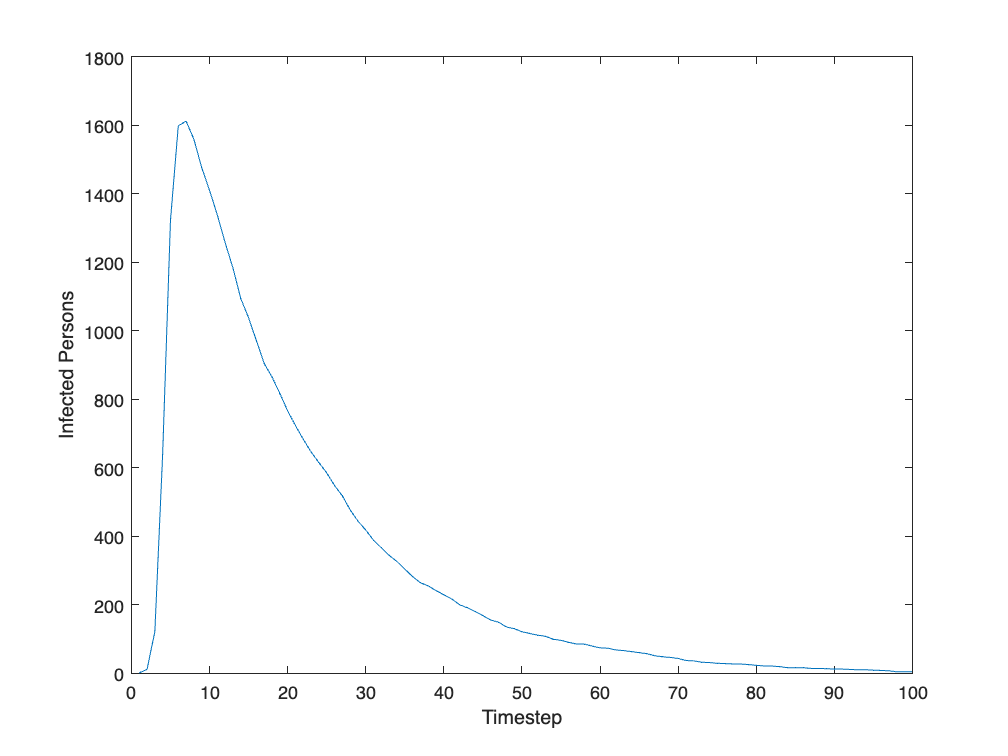

% Visualize
figure()
plot(I_count); hold on;
xlabel('Timestep')
ylabel('Infected Persons')

We can observe from the graph that the total number of infected individuals peak after a steep increase in infections in the beginning and then gradually decrease till the end of the simulation.

% assertions
assert(all(diag(M_pods) == 0), 'The diagonal of M should be zeros')
disp('Assertions passed!')

Assertions passed!


Since we know that the agent-based model is a random model, it cause a lot of variation when it is run every time. Therefore, the model is simulated multiple times (i.e. 100 times) with the same settings to find an average prediction curve.

% Set the number of replications for the agent-based model
n_realizations = 100;

% Run each simulation for 100 timesteps
T_simulation = 100;

The following code creates zeros matrices for storing the simulation results in the 'ensemble' matrices with size equal to the (number of timesteps, number of replications) of the simulation.

% Reserve space for simulation results
I_ensemble = zeros(T_simulation, n_realizations);
I_ensemble_D1 = zeros(T_simulation, n_realizations);
I_ensemble_D2 = zeros(T_simulation, n_realizations);
I_ensemble_C1 = zeros(T_simulation, n_realizations);
I_ensemble_C2 = zeros(T_simulation, n_realizations);
I_ensemble_M = zeros(T_simulation, n_realizations);
I_ensemble_I = zeros(T_simulation, n_realizations);

Then, we set the parameter values and a random seed which makes sure that the simulation results give the exact same output every time the model is run. 

% Set the random seed. 
rng(101)

% Set parameter values
infection_rate = 0.001; recovery_rate = 0.06;

The model is then simulated 100 times using the following loop function for the whole model and for individual pods as well.

% Generate the sample of results
for i = 1 : n_realizations

    % Run a single simulation
    [Sh, Ih, Rh] = simulate_absir(M_pods, Iv0, T_simulation, infection_rate, recovery_rate);
    % Summarize and store the infection history
    I_ensemble(:, i) = sum(Ih, 1);

    % Simulate individual pods
    Iv0_D1 = zeros(D_1, 1);
    Iv0_D1(1) = 1;
    rng(101)
    [~, Ih_D1, ~] = simulate_absir(M_pods(1:D_1, 1:D_1), Iv0_D1, T_simulation, infection_rate, recovery_rate);
    I_count_D1 = sum(Ih_D1, 1);
    I_ensemble_D1(:, i) = sum(Ih_D1, 1);

    Iv0_D2 = zeros(D_2, 1);
    Iv0_D2(1) = 1;
    rng(101)
    [~, Ih_D2, ~] = simulate_absir(M_pods(1+D_1 : D_2+D_1, 1+D_1 : D_2+D_1), Iv0_D2, T_simulation, infection_rate, recovery_rate);
    I_count_D2 = sum(Ih_D2, 1);
    I_ensemble_D2(:, i) = sum(Ih_D2, 1);

    Iv0_C1 = zeros(C_1, 1);
    Iv0_C1(1) = 1;
    rng(101)
    [~, Ih_C1, ~] = simulate_absir(M_pods(1+D_1+D_2 : D_1+D_2+C_1, 1+D_1+D_2 : D_1+D_2+C_1), Iv0_C1, T_simulation, infection_rate, recovery_rate);
    I_count_C1 = sum(Ih_C1, 1);
    I_ensemble_C1(:, i) = sum(Ih_C1, 1);

    Iv0_C2 = zeros(C_2, 1);
    Iv0_C2(1) = 1;
    rng(101)
    [~, Ih_C2, ~] = simulate_absir(M_pods(1+D_1+D_2+C_1: D_1+D_2+C_1+C_2, 1+D_1+D_2+C_1: D_1+D_2+C_1+C_2), Iv0_C2, T_simulation, infection_rate, recovery_rate);
    I_count_C2 = sum(Ih_C2, 1);
    I_ensemble_C2(:, i) = sum(Ih_C2, 1);

    Iv0_M = zeros(M, 1);
    Iv0_M(1) = 1;
    rng(101)
    [~, Ih_M, ~] = simulate_absir(M_pods(1+D_1+D_2+C_1+C_2: D_1+D_2+C_1+C_2+M, 1+D_1+D_2+C_1+C_2: D_1+D_2+C_1+C_2+M), Iv0_M, T_simulation, infection_rate, recovery_rate);
    I_count_M = sum(Ih_M, 1);
    I_ensemble_M(:, i) = sum(Ih_M, 1);

    Iv0_I = zeros(I, 1);
    Iv0_I(1) = 1;
    rng(101)
    [~, Ih_I, ~] = simulate_absir(M_pods(1+D_1+D_2+C_1+C_2+M: D_1+D_2+C_1+C_2+M+I, 1+D_1+D_2+C_1+C_2+M: D_1+D_2+C_1+C_2+M+I), Iv0_I, T_simulation, infection_rate, recovery_rate);
    I_count_I = sum(Ih_I, 1);
    I_ensemble_I(:, i) = sum(Ih_I, 1);


end

The mean is then calculated for the stored simulation results for each of the pods and the whole model.

% Compute the mean
I_mean = mean(I_ensemble, 2);
I_mean_D1 = mean(I_ensemble_D1, 2);
I_mean_D2 = mean(I_ensemble_D2, 2);
I_mean_C1 = mean(I_ensemble_C1, 2);
I_mean_C2 = mean(I_ensemble_C2, 2);
I_mean_M = mean(I_ensemble_M, 2);
I_mean_I = mean(I_ensemble_I, 2);

The multiple simulations and the mean curve of the simulations is plotted using the following code.

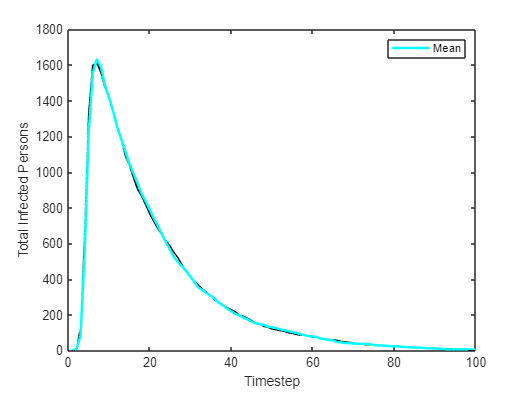

% Visualize
figure()
plot(I_ensemble, 'k-', 'LineWidth', 0.1, 'HandleVisibility', 'off'); hold on;
plot(I_mean, 'c-', 'LineWidth', 1.0, 'DisplayName', 'Mean curve');
xlabel('Timestep')
ylabel('Total Infected Persons')
legend()

As we can observe from the graph, the black lines denote the multiple simulations of the model and the fluroscent blue line indicates the mean curve for all the simulations. The graph results indicate that the maximum cumulative number of infected individuals reached around 1600 at roughly the 10th timestep. We can also observe a steep increase in infections until the peak total infections and then a gradual decrease until the end of the simulation.

The below code plots the mean curves for the simulation of each of the individual pods. To reduce complexity in visualizing the graph, multiple simulation results have not been plotted, rather only the mean results have been displayed.

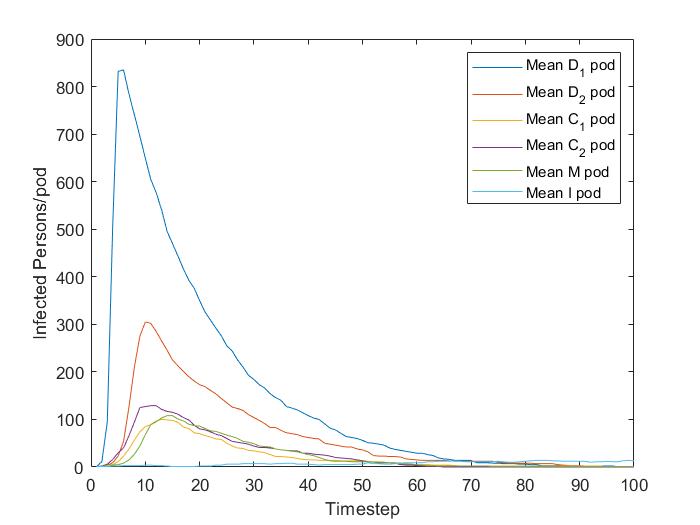

figure()
plot(I_mean_D1, 'DisplayName', 'Mean D_1 pod'); hold on;
plot(I_mean_D2, 'DisplayName', 'Mean D_2 pod');
plot(I_mean_C1, 'DisplayName', 'Mean C_1 pod');
plot(I_mean_C2, 'DisplayName', 'Mean C_2 pod');
plot(I_mean_M, 'DisplayName', 'Mean M pod');
plot(I_mean_I, 'DisplayName', 'Mean I pod');
xlabel('Timestep')
ylabel('Infected Persons/pod')
legend()

The graph clearly indicates the total number of infected individuals in each pod. We can observe how different pods show different intensities of peak infected cases throughout the simulation in the model. 

#### Validation

Our model is primarily based on factors obtained from research. Therefore, the most effective way to validate our model is to verify the research synthesis matrix and its sources, which corresponds to the data of total number of infections in migrants workers' dorms and the rates of infection, recovery, social connectivity, etc. 

We can also conclude from the New York Times source that the pods used in this model were responsible for infections in the migrant workers' dorms:

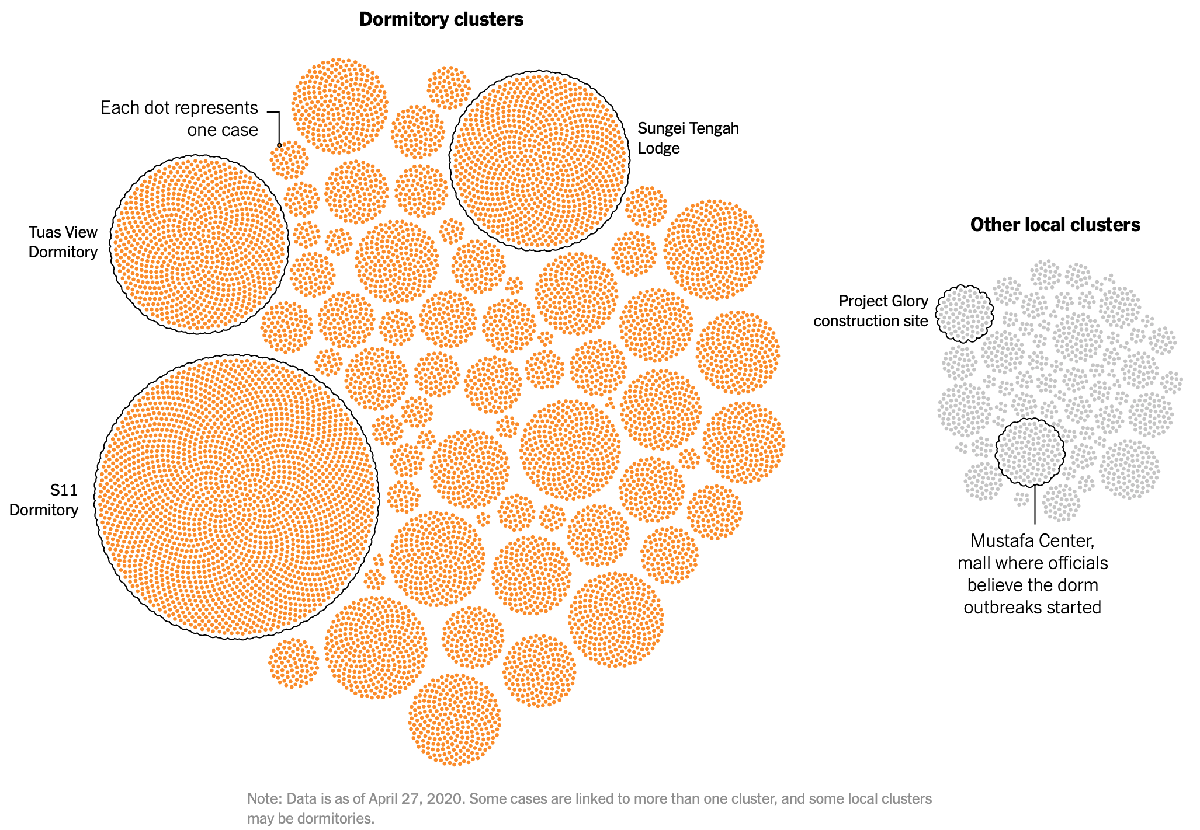

To infer that the migrant worker dorms in Singapore had very high infection rates, the following graph compares the daily new cases of infection between the migrant workers' dorms and the general population of Singapore. We can clearly observe that the proportion of COVID-19 infections in the dorms is significantly higher than their share in the overall population of Singapore, highlighting the high rates of infectivity.

“Number of new cases of confirmed COVID-19 in Singapore, 1 March–5 May 2020 [Source: Ministry of Health]” (BMJ)

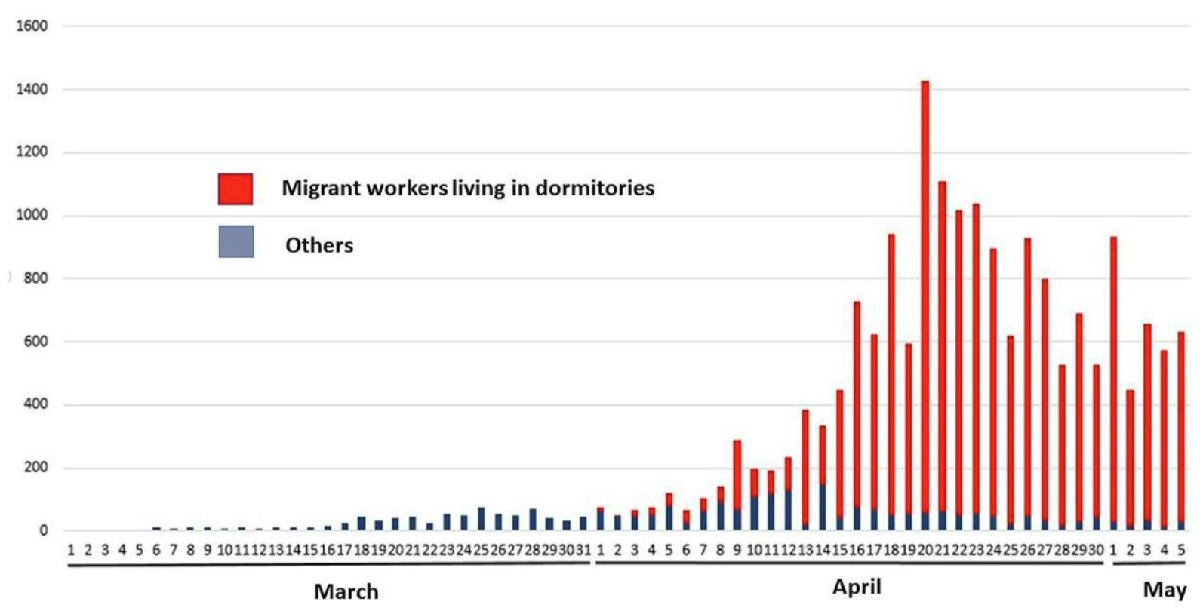

## `Interpretation`

The results indicate that the maximum intensity of peak infections is affected directly by adjusting the infection rate (probabilistic), recovery rate (probabilistic), and edge weights within the pods. Also, we find out that the maximum infected individuals in each pod reaches a value as desired by our question of modeling the effect of different policies, movements, etc. on migrants workers' dorms disease transmission. This is achieved by using unequal pod sizes and dfferent edge weights to model the living conditions in the dorms and interactions within migrant workers.

A few limitations of this agent-based SIR model include:

1)  Interactions with only individuals inside the migrant workers' model -

- In the case study, migrant workers also interacted with individuals outside the model in this project, which was the general population of Singapore. To avoid model complexity and focus on just modeling the situation of disease transmission in migrant workers' dorms, we did not include the general population in this model.

2)  Not having unequal edge weights for individuals across different pods -

- In a real-life model, individuals across different pods in the case-study would interact with each other at different rates. However, implementing that in this model would involve manipulating a lot of edge weights manually, as it is a very complicated and tedious task, and would also cause model complexity.

3)  Individuals bound to be in the same pod all throughout the simulation -

- As it is an agent-based model, we do not model stocks and flows, whereas the individuals stay in the same pods and have different levels of social connectivity. However, in the real-life case study, we observed that some migrant workers would move from different dormitories to construction sites or isolation areas, etc.

The next steps would involve creating pods for the general population of Singapore that could also model the social connections of individuals within the migrant workers' dorms, construction sites, isolation areas, etc. Also, we can try implementing a hybrid model, combining agent-based and compartmental models, to better model and simulate this specific case study scenario as has been done in various research studies.